# Examples of *k*-Means Clustering

In this reading you will perform *k*-means clustering on a three-dimensional data set. In the process, you will also learn how to determine the correct number of clusters using the [silhouette](https://www.mathworks.com/help/stats/silhouette.html) and [evalclusters](https://www.mathworks.com/help/stats/evalclusters.html) functions. 

When performing *k*-means clustering, follow these best practices:

- Use the `"Replicates"` name-value pair to search for the solution with the lowest total sum of distances

- Compare *k*-means clustering solutions for different values of *k* to determine an optimal number of clusters for your data.

- Evaluate clustering solutions by examining silhouette plots and silhouette values.

## Load Data Set

Load the `kmeansdata` data set.

load("kmeansdata.mat")

% Reduce the data set to three dimensions
X = X(:,1:3);

## Visualize Data

When possible, it is best to visualize the data. This can help you decide what steps to take next, as well as better interpret the information returned by the clustering functions. 

You can use [stackedplot](https://www.mathworks.com/help/matlab/ref/stackedplot.html) with this data to view each feature in a separate plot.

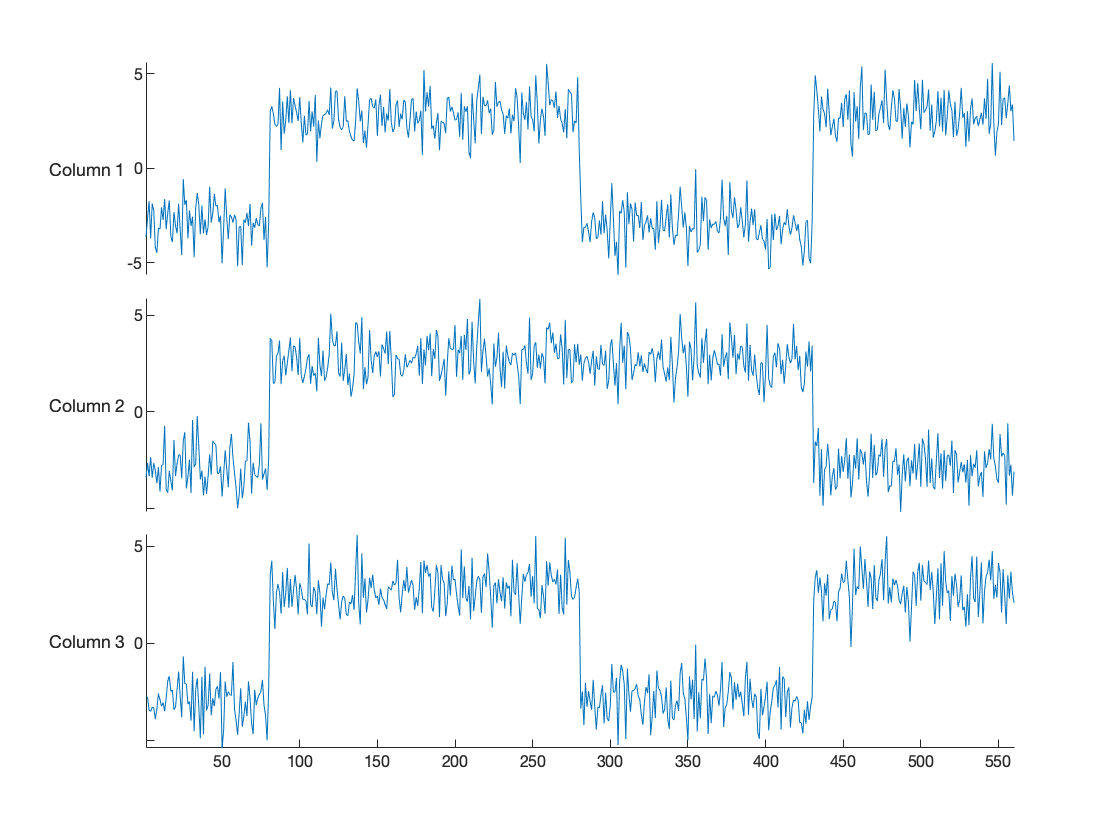

stackedplot(X);

Each column of variable `X` is a feature in the data set. The data here is made up of various square waves.

## **Create Clusters**

Use `kmeans` to group the data into clusters. Start with $k=2$ and `dist = squeclidean` and use **Run Section** to view the results. Then use the drop down menus to explore how the results change based on the number of clusters and the distance metric selected. The code in this section will automatically run when you make a new selection.

- How many clusters would you create based on all the information you see here?

- What distance metric(s) would you choose for this data?

Because `kmeans` uses random starting points, the `"Replicates"` name-value pair is included to help find the best solution by running the clustering algorithm the indicated number of times. The result with the lowest total sum of distances is returned.

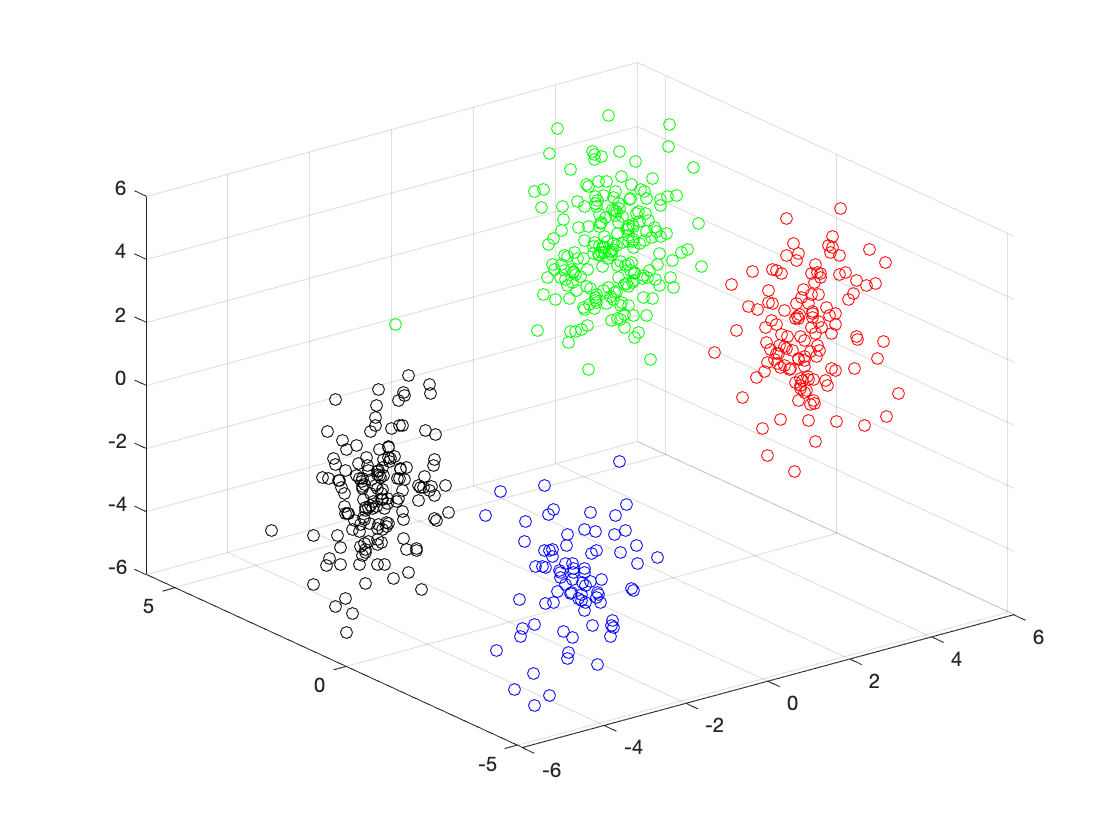

k=4; % Set the number of clusters
idx = kmeans(X,k,"Distance","sqeuclidean","Replicates",5);
c = [0 0 0; 1 0 0; 0 1 0; 0 0 1; 0 1 1]; % Create a list of colors to use for indicating cluster assignment
scatter3(X(:,1),X(:,2),X(:,3),[],c(idx,:))

### **A Note on "**`Replicates"`

Set $k=4$ and `"Replicates"` to 1 then click **Run Section** ten times. Observe the plotted results each time. 

- Do you notice any clusters you would consider incorrect?

- Why do you think the cluster colors move around?

Set `"Replicates"` back to 5 and click **Run Section** ten times. Observe the plotted results each time.

- The cluster colors still move around. Does this confirm what you thought before?

- Do you notice any cluster assignments you would consider incorrect? Why or why not?

The solution that `kmeans` reaches sometimes depends on the starting points. These are determined randomly by default. Because of this, the cluster order may change even if the end result does not. For example, Cluster 1 is always black, but which cluster is labeled as 1 is chosen at random. Using the `"Replicates"` name-value pair does not affect this.

Another possible effect of selecting random starting points is that other solutions (local minima) may be found. You might have seen some results that looked like this when `"Replicates"` was set to 1. Because this outcome is uncommon here, setting `"Replicates"` to 5 is enough to prevent it from being returned as a result.

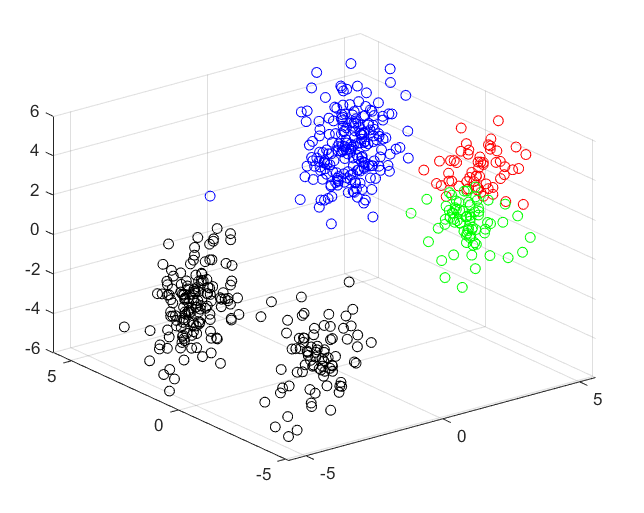

## Evaluate Clusters with Silhouette Plots

By visualizing the results in three dimensions, it is clear there should be 4 clusters. But what if the clusters were not as obvious, or your data had more than 3 dimensions? How can you determine the best number of clusters?

Silhouette plots display a measure of how similar a point is to other points in the same cluster compared to points in different clusters using normalized values ranging from -1 to 1. Points that are well matched to their cluster and poorly matched to other clusters have a value of 1. A value of -1 suggests points that are probably assigned to the wrong cluster. You can vary the value of k and use silhouette plots to visually compare the resulting cluster quality. 

Run the code in the following sections multiple times to see how the results can vary.

### 5 Clusters

To begin, inspect the silhouette plot for $k=5$. Be sure to use the same distance metric for both `kmeans` and `silhouette`.

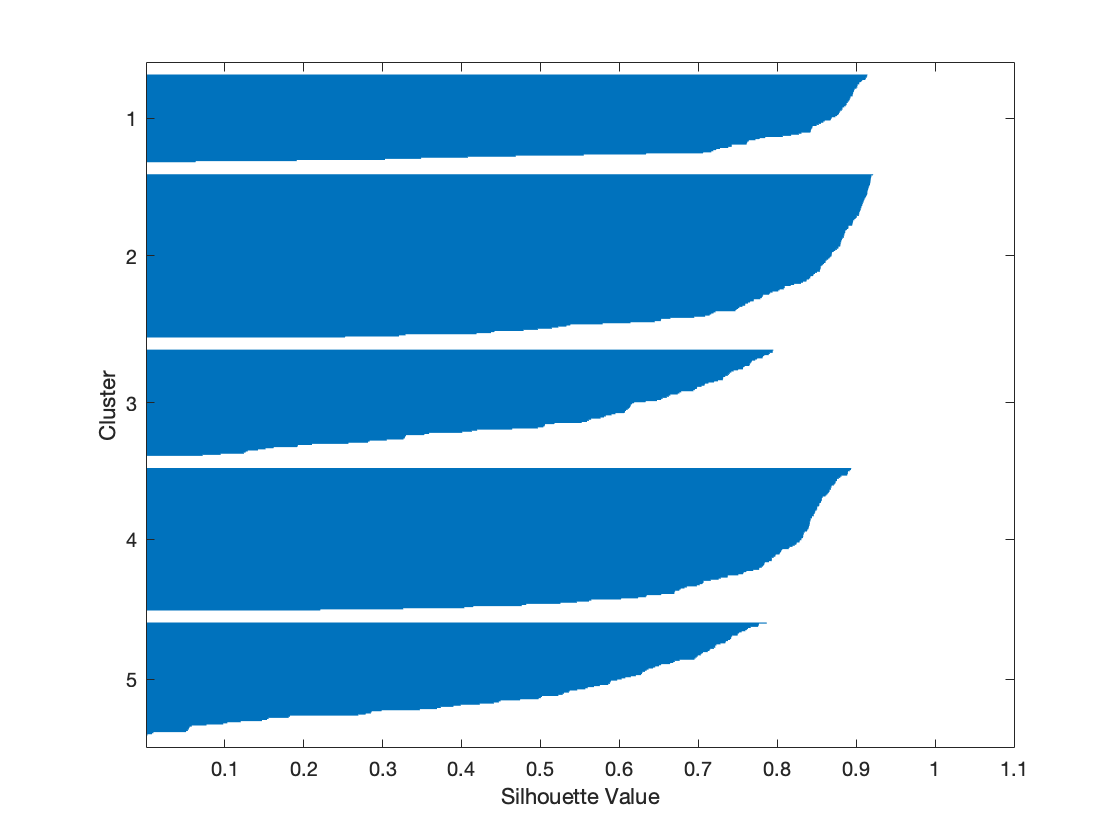

idx5 = kmeans(X,5,"Distance","sqeuclidean","Replicates",15);
[silh5,h] = silhouette(X,idx5,"sqEuclidean");
xlabel("Silhouette Value")
ylabel("Cluster")

The silhouette plot shows there are a couple clusters where many points have low silhouette values. This indicates that these two clusters may not be well separated. Some clusters may also have negative values, suggesting some points might be assigned incorrectly. Run the code in this section multiple times to see how the results vary.

A more quantitative approach is to compute the average silhouette value, which can then be compared to silhouette values for different values of k.

s5 = mean(silh5)

s5 = 0.7075

### 4 Clusters

Let's see if we can do any better by reducing the number of clusters. Repeat the process using $k=4$.

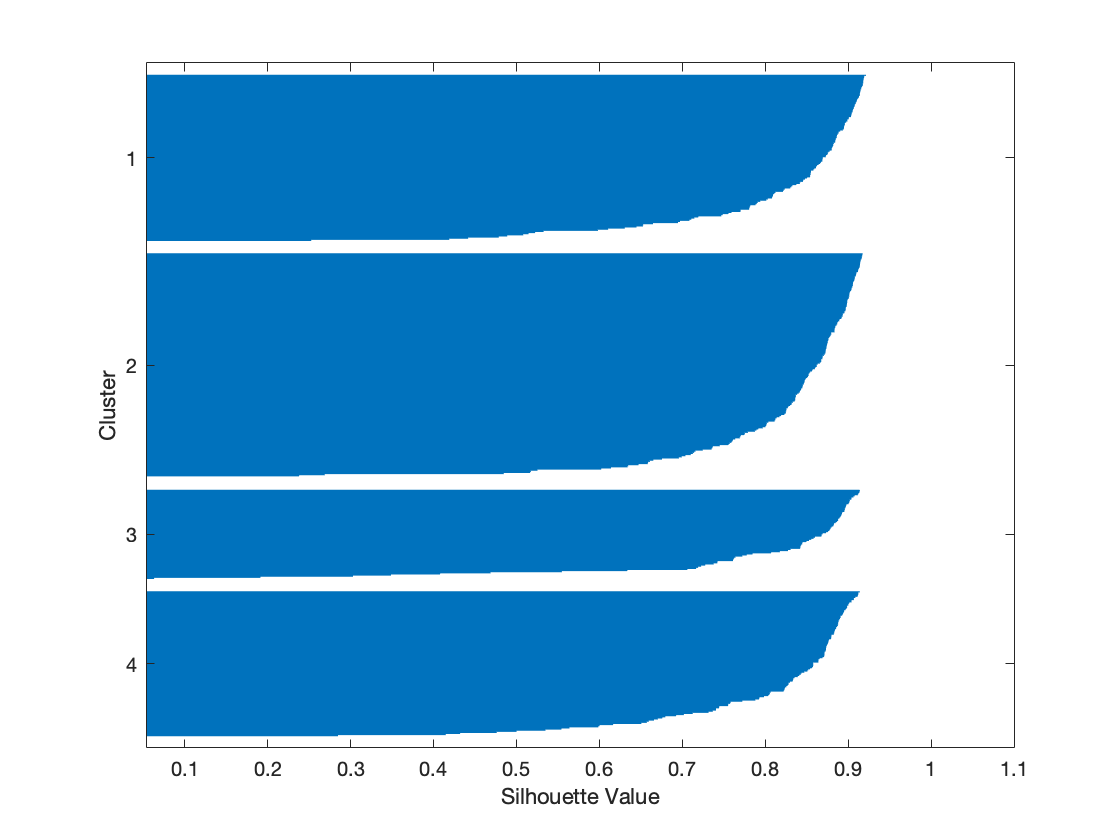

idx4 = kmeans(X,4,"Distance","sqeuclidean","Replicates",5);
[silh4,h] = silhouette(X,idx4,"sqEuclidean");
xlabel("Silhouette Value")
ylabel("Cluster")

There are no negative silhouette values, and here are less points with low silhouette values, indicating that the separation between each cluster is improved. 

Compute the mean silhouette value and compare it with the results for when $k=5$.

s4 = mean(silh4)

s4 = 0.8200

 In general, larger silhouette values mean better cluster quality. These results suggest that 4 clusters are better than 5.

### 3 Clusters

Repeat the steps one more time for $k=3$.

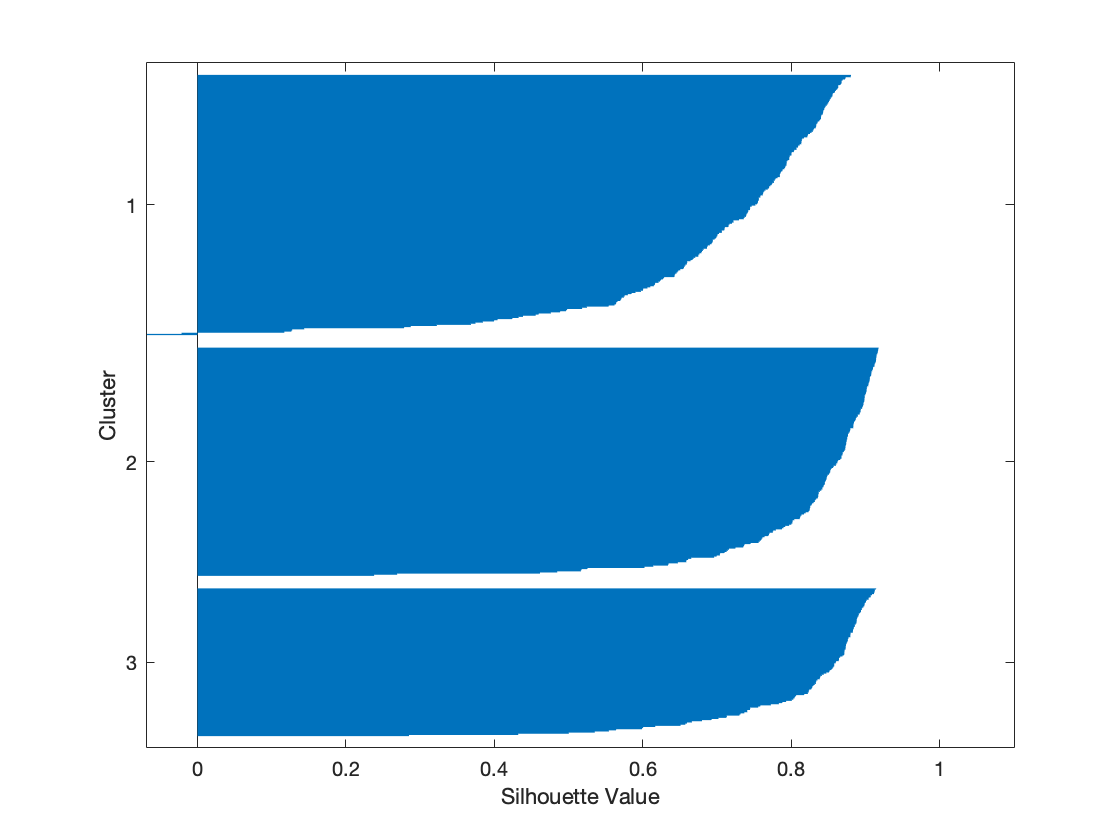

idx = kmeans(X,3,"Distance","sqeuclidean","Replicates",5);
[silh,h] = silhouette(X,idx,"sqEuclidean");
xlabel("Silhouette Value")
ylabel("Cluster")

mean(silh)

ans = 0.7761

- Compare the new mean silhouette value for 3 clusters to those for 4 and 5 clusters. What do the results suggest? 

- Change the number of clusters to 2 and compare the new mean silhouette value. 

- How many clusters would you create based on all the information you now have?

## Evaluate Clusters with `evalclusters`

Although silhouette values are insightful, they alone cannot be used to determine the correct number of clusters. Here, you were able to visualize the data and the silhouette values manually to determine the optimal number of clusters. Rather than go through this process manually, you can automate it using `evalclusters`. This function allows you to specify a range of clusters to test. The output is a cluster evaluation variable containing detailed information about the evaluation. 

Let's use `evalclusters` to determine the optimal number of clusters (between 2 and 6) for this data set using `kmeans` to cluster the data and silhouette plots to evaluate their quality. 

clustev = evalclusters(X,"kmeans","silhouette","KList",2:6)

clustev =   SilhouetteEvaluation with properties:

    NumObservations: 560
         InspectedK: [2 3 4 5 6]
    CriterionValues: [0.7563 0.7761 0.8200 0.7075 0.6715]
           OptimalK: 4


The `OptimalK` property indicates the optimal number of clusters. To return this value to a variable, use the following syntax.

kbest = clustev.OptimalK

kbest = 4

## Further Practice

For this reading, we reduced a four-dimensional data set down to three dimensions. 

Practice what you have learned by creating the optimal k-means clustering for the original data set. 

- What is the optimal number of clusters?

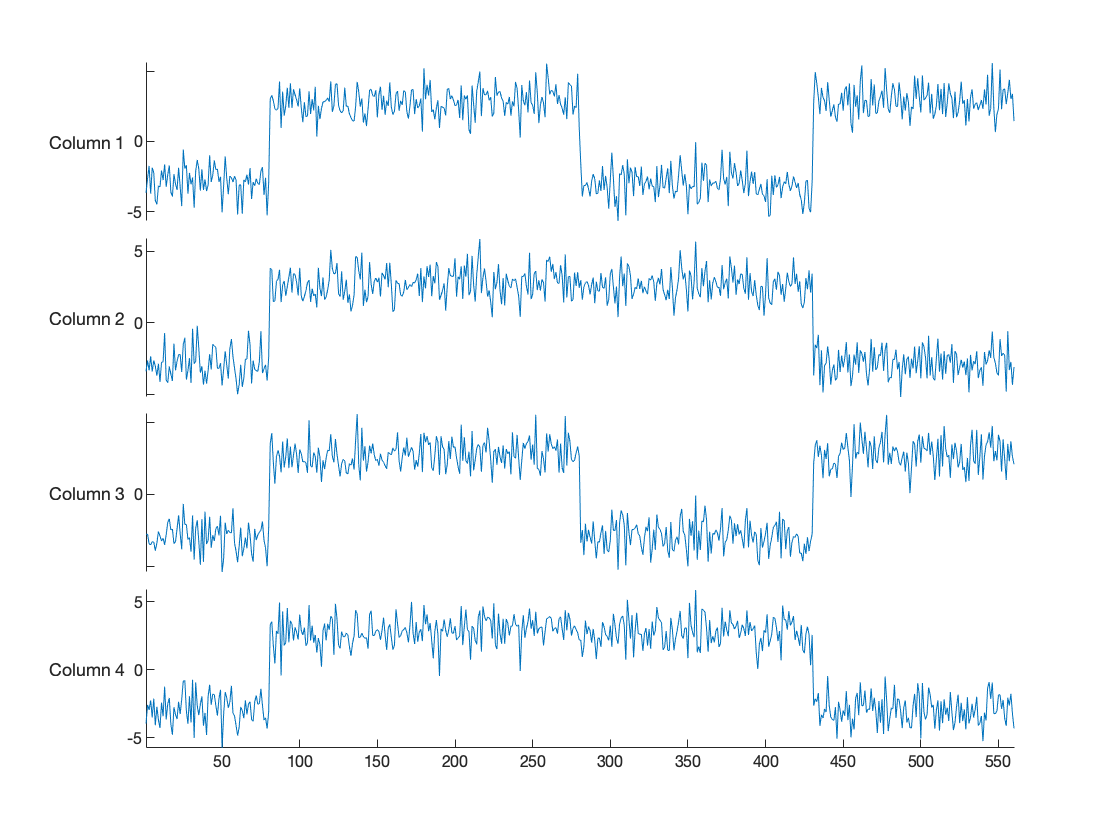

load("kmeansdata.mat")
stackedplot(X);

clustev = evalclusters(X,"kmeans","silhouette","KList",2:6)

clustev =   SilhouetteEvaluation with properties:

    NumObservations: 560
         InspectedK: [2 3 4 5 6]
    CriterionValues: [0.6317 0.7167 0.8575 0.7237 0.6354]
           OptimalK: 4


## References

- [Cluster Analysis using MATLAB](https://www.mathworks.com/help/stats/cluster-analysis.html)